% Script para gerar o Diagrama de Bode do sistema de posição do rastreador solar

clear; clc; close all;

% --- 1. Definição dos Parâmetros do Sistema ---
% Estes valores são baseados na Tabela 1 do documento de referência 
Ra = 1.0;      % Resistência de Armadura (Ohm) 
La = 0.5;      % Indutância de Armadura (H) 
Kt = 0.01;     % Constante de Torque (N.m/Amp) 
Kb = 0.01;     % Constante da F.C.E.M. (V/rad/sec) 
J_motor = 0.01;% Inércia do Rotor (kg.m^2) 
b_motor = 0.1; % Atrito do Rotor (N.m.s/rad) 
J_panel = 0.05;% Inércia do Painel (kg.m^2) 
b_panel = 0.02;% Atrito do Painel (N.m.s/rad) 

% Parâmetros totais (motor + carga) 
J_total = J_motor + J_panel; % 
b_total = b_motor + b_panel; % 

% --- 2. Criação da Função de Transferência de Posição P(s) ---
% P(s) = Theta(s)/Va(s) - Equação 15 do documento 
numP = [Kt];
denP = [La*J_total   (Ra*J_total + La*b_total)   (Ra*b_total + Kt*Kb)   0];
P_motor_position = tf(numP, denP);

disp('Função de Transferência de Posição P(s):');

Função de Transferência de Posição P(s):


printsys(numP, denP, 's');

 
num/den = 
 
                0.01
   ------------------------------
   0.03 s^3 + 0.12 s^2 + 0.1201 s


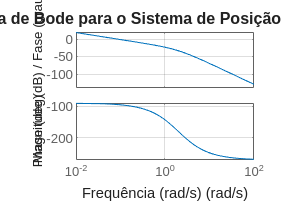


% --- 3. Geração e Formatação do Diagrama de Bode ---
figure('Name', 'Diagrama de Bode');
bode(P_motor_position); % Comando para gerar o plot 
grid on;
title('Diagrama de Bode para o Sistema de Posição (Malha Aberta)', 'FontSize', 12);
xlabel('Frequência (rad/s)');
ylabel('Magnitude (dB) / Fase (graus)');